# 1.3.08 Символьная алгебра

**Практическое занятие**

Периодическая функция с периодом T=2L может быть разложена в тригонометрический ряд Фурье вида:


$$f\left(x\right)=\frac{a_0 }{2}+\sum_{k=1}^{\infty } \left(a_k \cdot \mathrm{cos}\left(\frac{\pi kx}{L}\right)+b_k \cdot \mathrm{sin}\left(\frac{\pi kx}{L}\right)\right),$$


где $a_0$, $a_k$и $b_k$ являеются коэффициентами Фурье, и определяются по формулам Эйлера-Фурье:


$$\begin{cases} 
a_k =\frac{1}{L}\int_{-L}^L f\left(x\right)\mathrm{cos}\left(\frac{\pi kx}{L}\right)\mathrm{dx},k=0,1,2\;\ldotp \ldotp \ldotp \ldotp, \\
b_k =\frac{1}{L}\int_{-L}^L f\left(x\right)\mathrm{sin}\left(\frac{\pi kx}{L}\right)\textrm{dx},k=0,1,2\;\ldotp \ldotp \ldotp \ldotp. 
\end{cases}$$


Для заданной функции$f\left(x\right)$ найдите коэффициенты Фурье в аналитическом виде, разложите функцию в ряды Фурье с различным количеством членов ряда: 3, 5, 7, 50. Постройте график функции $f\left(x\right)$ и ее разложений в ряд Фурье с различным числом членов ряда. Функция $f\left(x\right)$-периодическая, и представляет собой меандр с периодом $T=2\pi$, на отрезке $\left.\lbrack -\pi ,\pi \right)$ описывается следующим выражением:


$$f\left(x\right)=\left\lbrace \begin{array}{ccc}
1 & \textrm{if}\; & x\in \left\lbrack -\pi ,\;0\right)\\
0 & \textrm{if} & \;x\in \left\lbrack 0,\pi \right)
\end{array}\right.$$


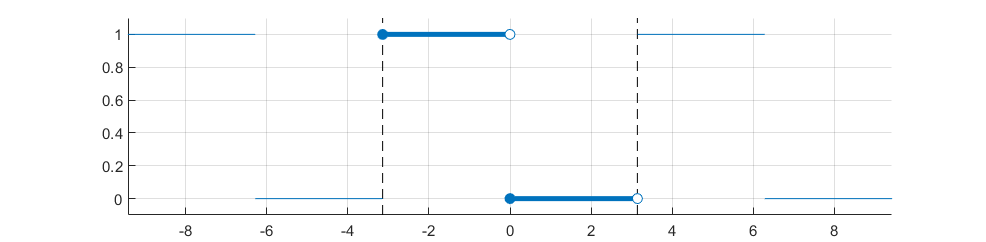

#### 1. Создайте символьные переменные:

 $x$- независимая переменная, $k$- количество членов ряда.

#### 2. Задайте кусочно-линейную функцию $f\left(x\right)$

Воспользуйтесь командой `piecewise()`, проверить правильность задания функции можно построив ее график командой `fplot()`

$$f\_x = \left\{ \begin{array}{cl} 1 & \text{ if }x\in \left[-\pi ,0\right)\\ 0 & \text{ if }x\in \left[0,\pi \right] \end{array}\right.$$

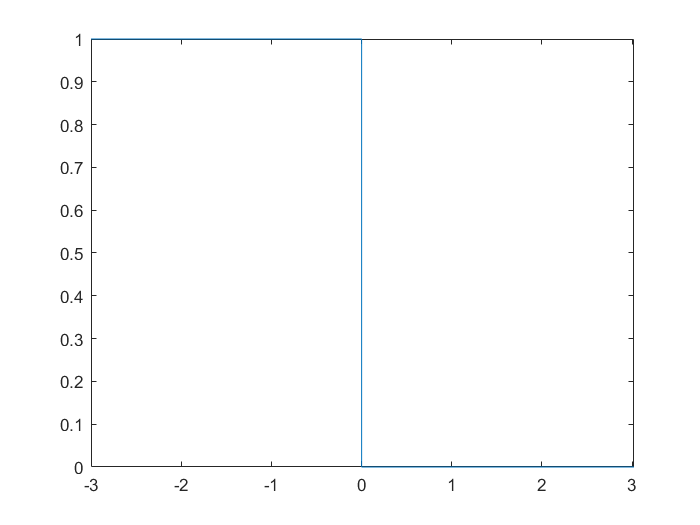

#### 3. Вычислите коэффициенты Фурье

% Задайте период функции T

% Вычислите полупериод L


$$L = \pi$$

% Найдите a_0, a_k, b_k


$$a\_0 = 1$$

$$a\_k = \frac{\sin\left(\pi \,k\right)}{k\,\pi }$$

$$b\_k = \frac{\cos\left(\pi \,k\right)-1}{k\,\pi }$$

#### 4. Разложите функцию в ряды Фурье с количеством членов ряда 3, 5, 7, 50

$$sum3 = \frac{1}{2}-\frac{2\,\sin\left(x\right)}{\pi }-\frac{2\,\sin\left(3\,x\right)}{3\,\pi }$$

$$sum5 = \frac{1}{2}-\frac{2\,\sin\left(5\,x\right)}{5\,\pi }-\frac{2\,\sin\left(x\right)}{\pi }-\frac{2\,\sin\left(3\,x\right)}{3\,\pi }$$

$$sum7 = \frac{1}{2}-\frac{2\,\sin\left(5\,x\right)}{5\,\pi }-\frac{2\,\sin\left(7\,x\right)}{7\,\pi }-\frac{2\,\sin\left(x\right)}{\pi }-\frac{2\,\sin\left(3\,x\right)}{3\,\pi }$$

$$sum50 = \frac{1}{2}-\frac{2\,\sin\left(5\,x\right)}{5\,\pi }-\frac{2\,\sin\left(7\,x\right)}{7\,\pi }-\frac{2\,\sin\left(9\,x\right)}{9\,\pi }-\frac{2\,\sin\left(11\,x\right)}{11\,\pi }-\frac{2\,\sin\left(13\,x\right)}{13\,\pi }-\frac{2\,\sin\left(15\,x\right)}{15\,\pi }-\frac{2\,\sin\left(17\,x\right)}{17\,\pi }-\frac{2\,\sin\left(19\,x\right)}{19\,\pi }-\frac{2\,\sin\left(21\,x\right)}{21\,\pi }-\frac{2\,\sin\left(23\,x\right)}{23\,\pi }-\frac{2\,\sin\left(25\,x\right)}{25\,\pi }-\frac{2\,\sin\left(27\,x\right)}{27\,\pi }-\frac{2\,\sin\left(29\,x\right)}{29\,\pi }-\frac{2\,\sin\left(31\,x\right)}{31\,\pi }-\frac{2\,\sin\left(33\,x\right)}{33\,\pi }-\frac{2\,\sin\left(35\,x\right)}{35\,\pi }-\frac{2\,\sin\left(37\,x\right)}{37\,\pi }-\frac{2\,\sin\left(39\,x\right)}{39\,\pi }-\frac{2\,\sin\left(41\,x\right)}{41\,\pi }-\frac{2\,\sin\left(43\,x\right)}{43\,\pi }-\frac{2\,\sin\left(45\,x\right)}{45\,\pi }-\frac{2\,\sin\left(47\,x\right)}{47\,\pi }-\frac{2\,\sin\left(49\,x\right)}{49\,\pi }-\frac{2\,\sin\left(x\right)}{\pi }-\frac{2\,\sin\left(3\,x\right)}{3\,\pi }$$

#### 5. Упростите выражения, хранящиеся в переменных sum3, sum5, sum7 с помощью функции simplify()

$$sum3 = \frac{16\,{\sin\left(x\right)}^{3}-24\,\sin\left(x\right)+3\,\pi }{6\,\pi }$$

$$ans = \frac{-192\,{\sin\left(x\right)}^{5}+320\,{\sin\left(x\right)}^{3}-180\,\sin\left(x\right)+15\,\pi }{30\,\pi }$$

$$ans = \frac{3840\,{\sin\left(x\right)}^{7}-8064\,{\sin\left(x\right)}^{5}+5600\,{\sin\left(x\right)}^{3}-1680\,\sin\left(x\right)+105\,\pi }{210\,\pi }$$

$$ans = \frac{-2225263978719205082243525718835200\,{\sin\left(x\right)}^{49}+27839472755040267837429640907980800\,{\sin\left(x\right)}^{47}-163708344012191075001885158056919040\,{\sin\left(x\right)}^{45}+601451981341177007367143641055232000\,{\sin\left(x\right)}^{43}-1547837949595477334243028926201856000\,{\sin\left(x\right)}^{41}+2965145975236464272208013247800934400\,{\sin\left(x\right)}^{39}-4386248645493375358442842692884889600\,{\sin\left(x\right)}^{37}+5129849982071559353713741321218293760\,{\sin\left(x\right)}^{35}-4817330712330457410763377661181952000\,{\sin\left(x\right)}^{33}+3668903327722960482784382042505216000\,{\sin\left(x\right)}^{31}-2279622477117520489626589100978995200\,{\sin\left(x\right)}^{29}+1158606364740640863544136237370572800\,{\sin\left(x\right)}^{27}-481583882396800590517885049191268352\,{\sin\left(x\right)}^{25}+163241395551658882259971882352640000\,{\sin\left(x\right)}^{23}-44874418023200256796616420229120000\,{\sin\left(x\right)}^{21}+9919608194602162028725734998016000\,{\sin\left(x\right)}^{19}-1742474428214880213631591317504000\,{\sin\left(x\right)}^{17}+239370224482044150559491332505600\,{\sin\left(x\right)}^{15}-25174152214157287468696504320000\,{\sin\left(x\right)}^{13}+1969948321126368999325378560000\,{\sin\left(x\right)}^{11}-110353586507541967091838336000\,{\sin\left(x\right)}^{9}+4193591605494205645995264000\,{\sin\left(x\right)}^{7}-100074345131111725643068800\,{\sin\left(x\right)}^{5}+1342919285173265239440000\,{\sin\left(x\right)}^{3}-9684514075768739707500\,\sin\left(x\right)+96845140757687397075\,\pi }{193690281515374794150\,\pi }$$

#### 6. Постройте на одних осях график функции $f\left(x\right)$ и полученные разложения в ряд.

Current plot held